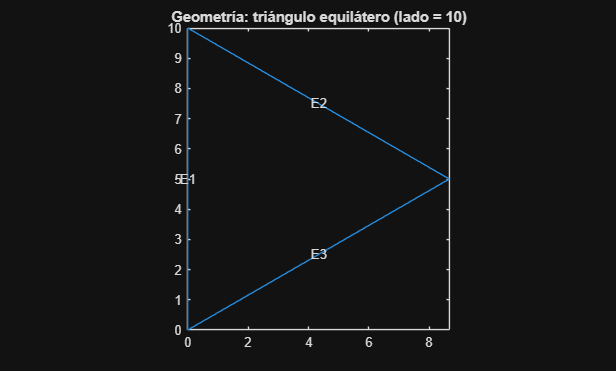

%% -------------------------------------------------------------
% Resolución de la ecuación del calor en un triángulo equilátero
% de lado 10, con vértices en (0,0), (0,10) y (5√3,5).
%
% - PDE: ∂u/∂t − Δu = 0
% - Dominio: triángulo equilátero, vértices A=(0,0), B=(0,10), C=(5√3,5)
% - Condición de contorno Dirichlet homogénea: u = 0 en los 3 lados
% - Condición inicial: gaussiana centrada en (xc, yc) = (5, (√3/6)*10)
% - Malla: triangular con Hmax = 0.5
% - Vector de tiempos: t ∈ [0, 10] con Δt = 0.05
%
% Observación general:
%   - Para la ecuación de calor (primer orden en t) se emplean 
%     m = 0, d = 1, c = 1, a = 0, f = 0. De este modo, MATLAB
%     no exige derivada inicial ∂u/∂t en t=0, solo u(x,y,0).
%   - Queremos que, al graficar, el eje vertical (u) permanezca
%     fijo de 0 a 1 durante toda la simulación, y que la escala
%     de color también vaya de 0 a 1. Para ello, tras cada llamada a pdeplot
%     indicamos zlim([0 1]) y caxis([0 1]).
%% -------------------------------------------------------------

clc
clear all

%% 1. Crear modelo PDE para problema transitorio (ecuación del calor).
%    No se pasa argumento “1” a createpde para evitar tratarlo como estacionario.
model = createpde();

%% 2. Definir la geometría: triángulo equilátero de lado 10
%    Vértices: A = (0,0), B = (0,10), C = (5*sqrt(3), 5).
%    Construcción de la descripción “R1” para decsg:
%      - 2: indica “polígono” de n vértices (en este caso 3 vértices)
%      - 3: número de vértices
%      - [x1, x2, x3]: coordenadas x = [ 0,   0,   5√3 ]
%      - [y1, y2, y3]: coordenadas y = [ 0,  10,   5   ]
L = 10;  % Longitud del lado del triángulo
R1 = [2, 3,   0,    0,    5*sqrt(3),    0,   10,    5]';
g  = decsg(R1);         % Decodifica la descripción geométrica
geometryFromEdges(model, g);

% (Opcional) Visualizar la geometría y numerar las aristas
figure
pdegplot(model, "EdgeLabels", "on")
title("Geometría: triángulo equilátero (lado = 10)")
axis equal

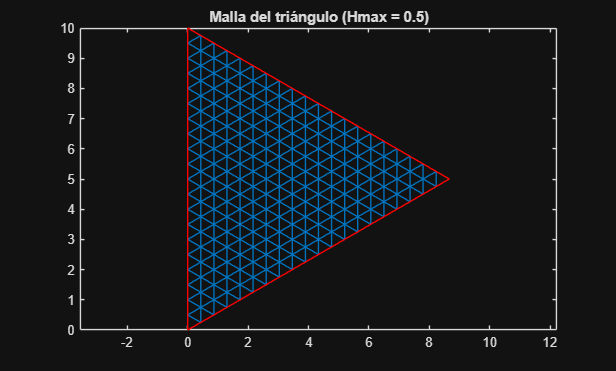


%% 3. Aplicar condición de contorno Dirichlet homogénea (u = 0) en las 3 aristas
%    Tras pdegplot, las aristas están etiquetadas como 1, 2 y 3, respectivamente.
applyBoundaryCondition(model, "dirichlet", "Edge", [1, 2, 3], "u", 0);

%% 4. Generar malla triangular con tamaño de elemento Hmax = 0.5
generateMesh(model, "Hmax", 0.5);

% (Opcional) Visualizar la malla para comprobar densidad y cobertura
figure
pdemesh(model)
title("Malla del triángulo (Hmax = 0.5)")
axis equal

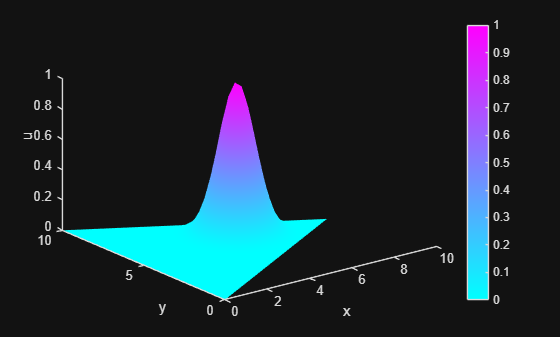

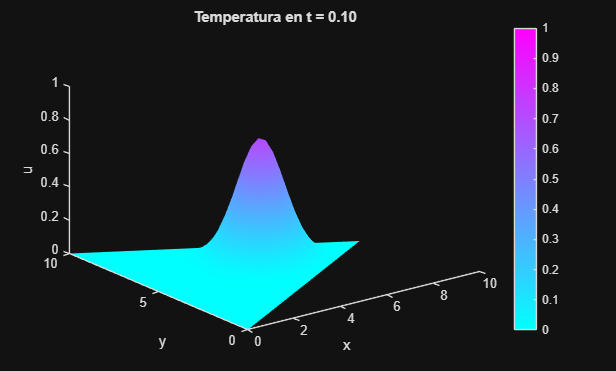

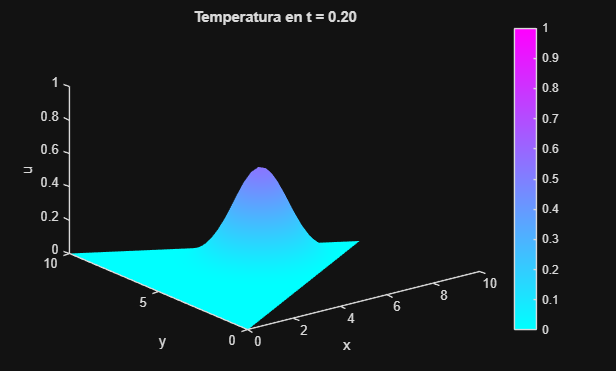

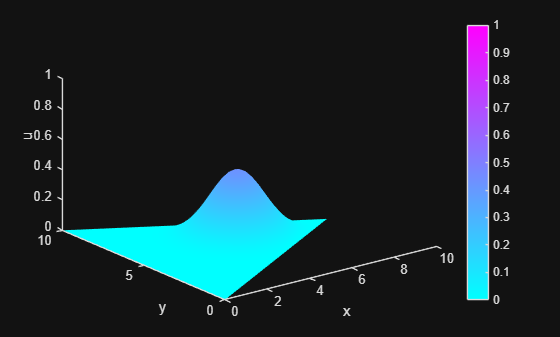

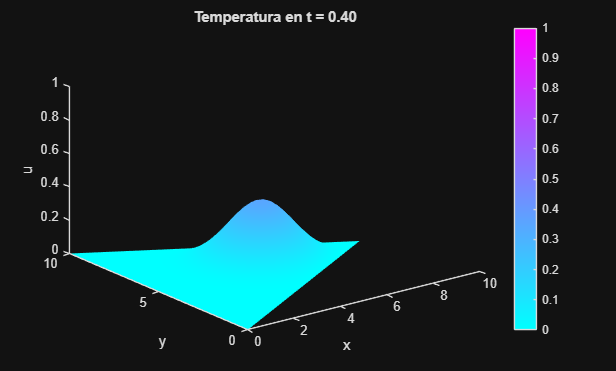

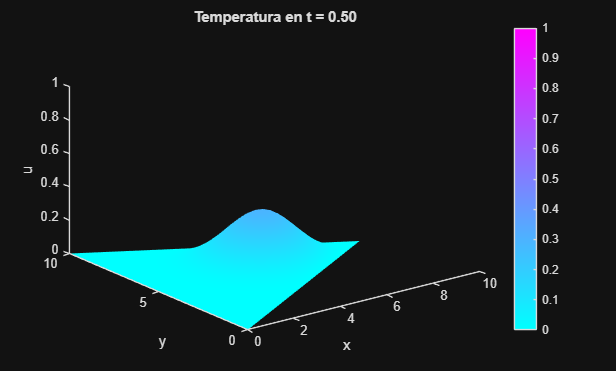

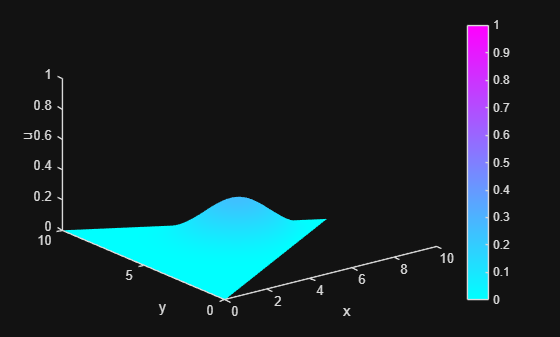

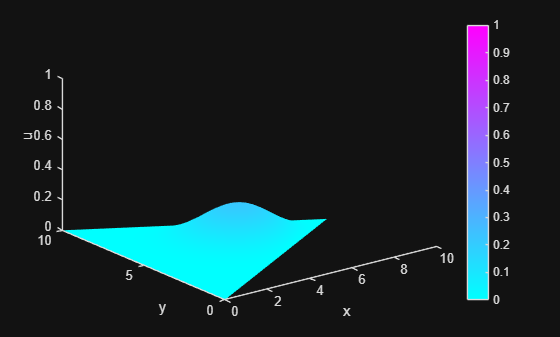


%% 5. Especificar coeficientes de la PDE para la ecuación del calor
%    La forma general que la toolbox acepta es:
%      m ∂^2u/∂t^2 + d ∂u/∂t - ∇·(c ∇u) + a u = f.
%    En nuestro caso, deseamos resolver:
%      ∂u/∂t - Δu = 0,
%    que equivale a asignar:
%      m = 0,    (no hay término de segundo orden en el tiempo)
%      d = 1,    (coeficiente multiplicando ∂u/∂t)
%      c = 1,    (difusividad unitaria para −∇·(c ∇u) = −Δu)
%      a = 0,    (sin amortiguamiento)
%      f = 0.    (sin fuente de calor)
specifyCoefficients(model, ...
    "m", 0, ...   % Sin término de segundo orden en t
    "d", 1, ...   % Término de primer orden: ∂u/∂t
    "c", 1, ...   % Difusividad unitaria → −Δu
    "a", 0, ...   % Sin término a·u
    "f", 0);      % Sin fuente interna

%% 6. Fijar la condición inicial: gaussiana centrada en (xc, yc)
%    Deseamos: u(x,y,0) = exp( - [ (x - xc)^2 + (y - yc)^2 ] ).
%    Donde tenemos:
%      xc = L/2 = 5,
%      yc = (√3/6)*L = (√3/6)*10 ≈ 2.8868.
xc = L / 2;                       % 5
yc = (sqrt(3) / 6.0) * L;         % (√3/6)*10 ≈ 2.8868
%    ¡Ojo! Para elevar cada componente a la potencia 2, hay que usar .^2:
%    (location.x – xc).^2   y   (location.y – yc).^2
setInitialConditions(model, ...
    @(location) exp( - ( (location.x - xc).^2 + (location.y - 2*yc).^2 ) ) );

%% 7. Definir vector de tiempos para simular (t ∈ [0, 10] con Δt = 0.05)
tlist = 0 : 0.01 : 1;  % Genera [0, 0.05, 0.10, 0.15, …, 10.00]

%% 8. Resolver la PDE transitoria
%    solvepde con vector de tiempos devuelve la evolución nodal para cada instante.
result = solvepde(model, tlist);
%    result.NodalSolution tendrá dimensión [NúmeroDeNodos × length(tlist)].

%% 9. Visualizar la solución en t = 10 (último instante) con eje u fijo en [0,1]
u_final = result.NodalSolution(:, end);  % Columna final → t = 10



% Supongamos que tlist es el vector de tiempos y result.NodalSolution
% contiene las soluciones nodales en cada columna (igual que antes).

% Asumimos que tlist es el vector de tiempos que va desde 0 hasta Tmax = 1,
% y que result.NodalSolution contiene en cada columna la solución nodal
% correspondiente a cada tiempo en tlist.

% Definimos los tiempos objetivo:
tiempos_obj = [0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1];

% Para cada tiempo objetivo encontramos el índice en tlist cuyo valor
% esté más cerca:
indices = zeros(size(tiempos_obj));
for k = 1:numel(tiempos_obj)
    [~, indices(k)] = min(abs(tlist - tiempos_obj(k)));
end

% Ahora generamos una figura independiente para cada uno de esos instantes:
for k = 1:numel(indices)
    idx = indices(k);
    
    figure
    u_temp = result.NodalSolution(:, idx);
    pdeplot(model, "XYData", u_temp, "ZData", u_temp);
    
    title(sprintf("Temperatura en t = %.2f", tlist(idx)));
    xlabel("x"), ylabel("y"), zlabel("u");
    
    colorbar
    zlim([0 1]);      % Mantiene el rango vertical de u en [0,1]
    caxis([0 1]);     % Escala de colores en [0,1]
    view(3)           % Vista 3D fija
    
    pause(0.1)
end